addpath("myfunctions\");
addpath("Sensorfusion smartphone\");

# TASK2

********************
* SensorDataReader started on 192.168.31.72:3400
********************
Connection accepted from 192.168.31.22:48148


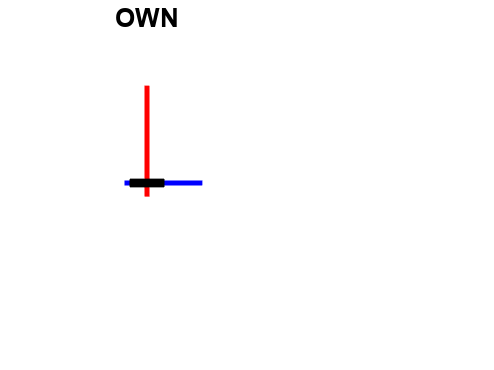

% [xhat, meas] = filterTemplate();

% save meas;

load("meas.mat");
meas_acc= meas.acc(:, ~any(isnan(meas.acc), 1));                                              
meas_gyr= meas.gyr(:, ~any(isnan(meas.gyr), 1));
meas_mag= meas.mag(:, ~any(isnan(meas.mag), 1));

%get mean and cov
[a_mu, a_Sigma] = get_mean_cov(meas_acc)

a_mu =    -0.0975
    0.3073
    9.8683


a_Sigma = 1.0e-03 *

    0.1894    0.1061   -0.0024
    0.1061    0.1394    0.0013
   -0.0024    0.0013    0.2128


[g_mu, g_Sigma] = get_mean_cov(meas_gyr)

g_mu =    -0.0000
    0.0001
   -0.0012


g_Sigma = 1.0e-04 *

    0.0024   -0.0001    0.0050
   -0.0001    0.0028   -0.0097
    0.0050   -0.0097    0.1949


[m_mu, m_Sigma] = get_mean_cov(meas_mag)

m_mu =    -4.9435
  -35.2368
 -168.4627


m_Sigma =     0.0885   -0.0055   -0.0048
   -0.0055    0.1117   -0.0080
   -0.0048   -0.0080    0.1085



%get pdf
[n_ax,Y_ax] =getnormpdf(a_mu(1,:),a_Sigma(1,1),0.001);
[n_ay,Y_ay] =getnormpdf(a_mu(2,:),a_Sigma(2,2),0.001);
[n_az,Y_az] =getnormpdf(a_mu(3,:),a_Sigma(3,3),0.001);

[n_gx,Y_gx] =getnormpdf(g_mu(1,:),g_Sigma(1,1),0.001);
[n_gy,Y_gy] =getnormpdf(g_mu(2,:),g_Sigma(2,2),0.001);
[n_gz,Y_gz] =getnormpdf(g_mu(3,:),g_Sigma(3,3),0.001);

[n_mx,Y_mx] =getnormpdf(m_mu(1,:),m_Sigma(1,1),0.001);
[n_my,Y_my] =getnormpdf(m_mu(2,:),m_Sigma(2,2),0.001);
[n_mz,Y_mz] =getnormpdf(m_mu(3,:),m_Sigma(3,3),0.001);

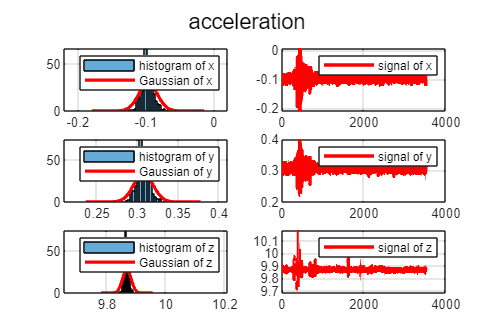

%plot
figure('Position',[300 300 600 400]);
subplot(3,2,1)
histogram(meas_acc(1,:),'Normalization','pdf');
hold on
plot(n_ax,Y_ax,'r','Linewidth',2);
hold off
grid on
legend('histogram of x','Gaussian of x')
subplot(3,2,2)
plot(1:length(meas_acc),meas_acc(1,:),'r','Linewidth',2);
grid on
legend('signal of x')

subplot(3,2,3)
histogram(meas_acc(2,:),'Normalization','pdf');
hold on
plot(n_ay,Y_ay,'r','Linewidth',2);
hold off
grid on
legend('histogram of y','Gaussian of y')
subplot(3,2,4)
plot(1:length(meas_acc),meas_acc(2,:),'r','Linewidth',2);
grid on
legend('signal of y')

subplot(3,2,5)
histogram(meas_acc(3,:),'Normalization','pdf');
hold on
plot(n_az,Y_az,'r','Linewidth',2);
hold off
grid on
legend('histogram of z','Gaussian of z')
subplot(3,2,6)
plot(1:length(meas_acc),meas_acc(3,:),'r','Linewidth',2);
grid on
legend('signal of z')

sgtitle("acceleration");

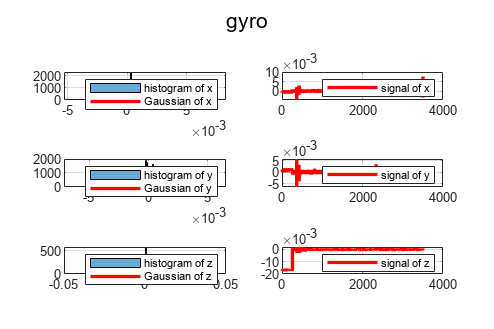

figure('Position',[300 300 600 400]);
subplot(3,2,1)
histogram(meas_gyr(1,:),'Normalization','pdf');
hold on
plot(n_gx,Y_gx,'r','Linewidth',2);
hold off
grid on
legend('histogram of x','Gaussian of x')
subplot(3,2,2)
plot(1:length(meas_gyr),meas_gyr(1,:),'r','Linewidth',2);
grid on
legend('signal of x')

subplot(3,2,3)
histogram(meas_gyr(2,:),'Normalization','pdf');
hold on
plot(n_gy,Y_gy,'r','Linewidth',2);
hold off
grid on
legend('histogram of y','Gaussian of y')
subplot(3,2,4)
plot(1:length(meas_gyr),meas_gyr(2,:),'r','Linewidth',2);
grid on
legend('signal of y')

subplot(3,2,5)
histogram(meas_gyr(3,:),'Normalization','pdf');
hold on
plot(n_gz,Y_gz,'r','Linewidth',2);
hold off
grid on
legend('histogram of z','Gaussian of z')
subplot(3,2,6)
plot(1:length(meas_gyr),meas_gyr(3,:),'r','Linewidth',2);
grid on
legend('signal of z')

sgtitle("gyro");

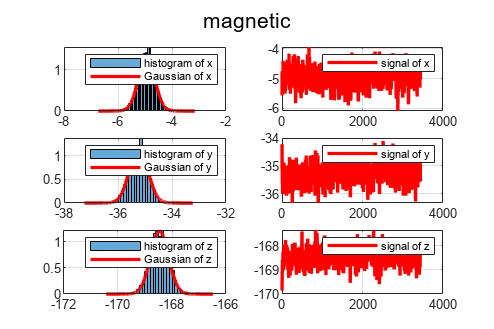

figure('Position',[300 300 600 400]);
subplot(3,2,1)
histogram(meas_mag(1,:),'Normalization','pdf');
hold on
plot(n_mx,Y_mx,'r','Linewidth',2);
hold off
grid on
legend('histogram of x','Gaussian of x')
subplot(3,2,2)
plot(1:length(meas_mag),meas_mag(1,:),'r','Linewidth',2);
grid on
legend('signal of x')

subplot(3,2,3)
histogram(meas_mag(2,:),'Normalization','pdf');
hold on
plot(n_my,Y_my,'r','Linewidth',2);
hold off
grid on
legend('histogram of y','Gaussian of y')
subplot(3,2,4)
plot(1:length(meas_mag),meas_mag(2,:),'r','Linewidth',2);
grid on
legend('signal of y')

subplot(3,2,5)
histogram(meas_mag(3,:),'Normalization','pdf');
hold on
plot(n_mz,Y_mz,'r','Linewidth',2);
hold off
grid on
legend('histogram of z','Gaussian of z')
subplot(3,2,6)
plot(1:length(meas_mag),meas_mag(3,:),'r','Linewidth',2);
grid on
legend('signal of z')

sgtitle("magnetic");

# TASK5

********************
* SensorDataReader started on 192.168.31.72:3400
********************
Connection accepted from 192.168.31.22:48246


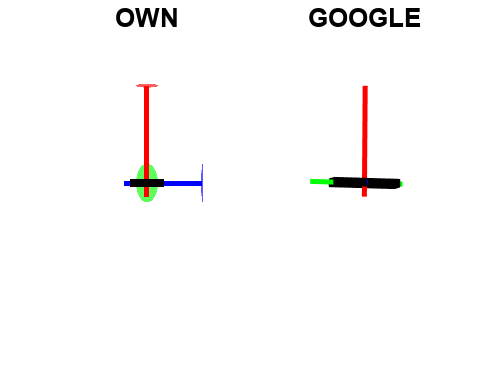

Unsuccessful connecting to client!
Make sure to start streaming from the phone *after*running this function!

[xhat, meas] = filterTASK5(); 

# TASK6